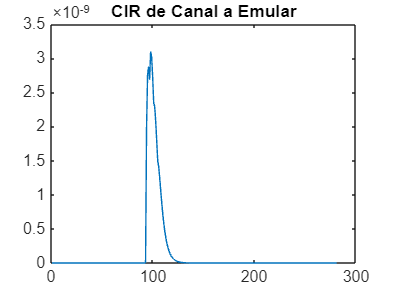

%% intro
clear all
rng("shuffle")
%rng(2,"twister")

run("main_channel.m")

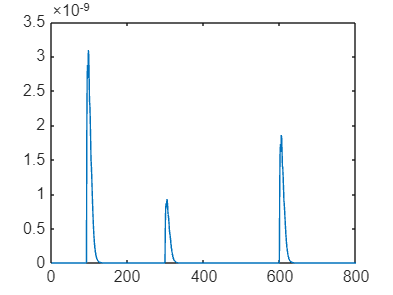


newresponse = zeros(1,800);
newresponse(1:281) = Final_response(1:281);
newresponse(300:451) = Final_response(94:245)*0.3;
newresponse(600:751) = Final_response(94:245)*0.6;

figure
plot(newresponse)


H = newresponse;

txPacket = generatePacket_OOK_BPSK(H);

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

Error in transmitterbeta>generatePacket_OOK_BPSK (line 187)
    txPacket = [ookPreamble;pilotChan;dataChan];


modulatedSignalTx = [txPacket'/max(txPacket)];


write_float_binary(modulatedSignalTx,'envioOOKyDATA.bin');

read = read_float_binary('envioOOKyDATA.bin')';

figure
plot(read(1:4001))
title("Data a enviar con canal convolucionado")



function v = write_float_binary (data, filename)

  %% usage: write_float_binary (data, filename)
  %%
  %%  open filename and write data to it as 32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  f = fopen (filename, 'wb');
  if (f < 0)
    v = 0;
  else
    v = fwrite (f, data, 'float');
    fclose (f);
  end
end


function v = read_float_binary (filename, count)

  %% usage: read_float_binary (filename, [count])
  %%
  %%  open filename and return the contents, treating them as
  %%  32 bit floats
  %%

  m = nargchk (1,2,nargin);
  if (m)
    usage (m);
  end

  if (nargin < 2)
    count = Inf;
  end

  f = fopen (filename, 'rb');
  if (f < 0)
    v = 0;
  else
    v = fread (f, count, 'float');
    fclose (f);
  end
end

function bits = demodulate_signal(signal, samples_per_bit)
    % Inicializar vector de bits
    num_bits = length(signal) / samples_per_bit;
    bits = zeros(1, num_bits);

    % Determinar el valor de cada bit
    for i = 1:num_bits
        segment = signal((i-1)*samples_per_bit + 1 : i*samples_per_bit);
        if mean(segment) > 0
            bits(i) = 1;
        else
            bits(i) = 0;
        end
    end
end


function ber = calculate_ber(bits_received, bits_original)
    % Verificar que los arreglos tengan la misma longitud
    if length(bits_received) ~= length(bits_original)
        error('Los arreglos de bits deben tener la misma longitud');
    end
    
    % Calcular el número de errores
    num_errors = sum(bits_received ~= bits_original);
    
    % Calcular el BER
    ber = num_errors / length(bits_original);
end


function txPacket = generatePacket_OOK_BPSK(H)
% GENERATEPACKET_OOK_BPSK Generates a three-part packet:
%   1) OOK preamble at passband
%   2) BPSK pilot (baseband) convolved with H
%   3) BPSK data (baseband) convolved with H
%
% INPUT:
%   H : (row or column vector) The artificial channel impulse response.
%
% OUTPUT:
%   txPacket : The final time-domain signal (column vector).
%
% Example usage:
%   H = [0.9 0.2 0.05];   % example channel
%   txPacket = generatePacket_OOK_BPSK(H);

    %% =============== 1) OOK PREAMBLE (passband) ===============
    Fs            = 2e6;        % sampling rate (Hz)
    Fc            = 1e5;        % carrier freq (Hz) for OOK preamble
    bitsPerPreamb = 16;
    samplesPerBit = 100;        % OOK upsampling factor
    % 16 bits example preamble
    preambleBits = [1 1 1 1  0 0 0 0  1 0 1 0  1 1 0 0];  % length = 16

    % Upsample to create OOK wave (0 or 1)
    preambleUps = repelem(preambleBits, samplesPerBit);  % 16*100=1600
    
    % Generate time vector for preamble
    tPreamb = (0:length(preambleUps)-1)' / Fs; 
    
    % Multiply by a carrier (passband OOK)
    ookPreamble = preambleUps .* cos(2*pi*Fc*tPreamb);

    %% =============== 2) BPSK PILOT (baseband) ===============
    % This block is RRC-filtered + convolved by H
    
    pilotLen  = 16;    % number of pilot bits (adjust as needed)
    pilotBits = randi([0 1], pilotLen, 1);  % or use a fixed pattern
    % Map bits to BPSK symbols: 0->-1, 1->+1
    pilotBPSK = 2*pilotBits - 1;

    % RRC filter design
    rolloff = 0.25;
    span    = 6;      % filter span in symbols
    sps     = 8;      % samples per symbol for BPSK blocks
    rrcFilt = rcosdesign(rolloff, span, sps, 'sqrt');

    % Upsample pilot bits
    pilotUp = upsample(pilotBPSK, sps);

    % Pulse-shape with RRC
    pilotRRC = filter(rrcFilt, 1, pilotUp);

    % Convolve with artificial channel H
    pilotChan = conv(pilotRRC, H, 'full');
    % pilotChan is now the baseband pilot block after channel
    
    %% =============== 3) BPSK DATA (baseband) ===============
    % Also RRC-filtered + convolved by H

    dataLen  = 200;       % number of data bits
    dataBits = randi([0 1], dataLen, 1);
    dataBPSK = 2*dataBits - 1;

    % Upsample & RRC
    dataUp   = upsample(dataBPSK, sps);
    dataRRC  = filter(rrcFilt, 1, dataUp);

    % Convolve with H
    dataChan = conv(dataRRC, H, 'full');
    % dataChan is the baseband data block after channel

    %% =============== 4) CONCATENATE ALL BLOCKS ===============
    % We place OOK preamble first, then the BPSK pilot (baseband),
    % then the BPSK data (baseband). 

    % Note: The OOK preamble is passband (carrier),
    % while the pilotChan/dataChan are purely baseband.
    txPacket = [ookPreamble;pilotChan;dataChan];

    % Make sure it's a column vector
    txPacket = txPacket(:);
end
